# What Kind of Flower is That?

This example uses transfer learning to train a deep network that can classify images of flowers into one of 12 species.

## Get training images

%This line of code gets the flower images from the folder where thay'er
%stored and names them according to the name of the sub-folder where
%they're stored.
flowerds = imageDatastore('Flowers','IncludeSubfolders',true,'LabelSource','foldernames');

Split into training and testing sets

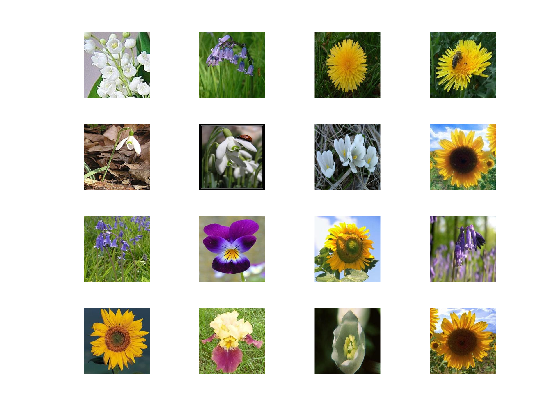

%This block of code splits the images in a ratio of 6:4 or 60:40%
%where 60% of the images is for training while the remaining 40% is for
%testing.
%Note: the 60% is randomised while the 40% are correctly labeled.
%And some of the images are displayed on the right side of the IDE
%randomly.
%The for loop displays images 1 to 16
[trainImgs,testImgs] = splitEachLabel(flowerds,0.6);
numTrainImages = numel(trainImgs.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(trainImgs,idx(i));
    imshow(I)
end

Determine the number of flower species

%This line of Code determines how many different sepcies of floweres are in
%the folder by counting the number of sub-folders, fetching and assigning
%their names to the numClasses variable
numClasses = numel(categories(flowerds.Labels));

## Create a network by modifying AlexNet

Get the layers from AlexNet

%In this Section we're using the alexnet network for the training so we
%assign the alexnet network to the variable net
%In this Section we get the layers of the alexnet network, which we'll
%modify to input and output layers to suit our need
net = alexnet;
layers = net.Layers;

Modify the classification and output layers

%In this block of Code we modify the alexnet layers
layers(end-2) = fullyConnectedLayer(numClasses); 
layers(end) = classificationLayer;

## Set training algorithm options

Lower the learning rate for transfer learning

%In this line of code we use a learning rate of 0.001 to as the training
%rate
options = trainingOptions('sgdm','InitialLearnRate', 0.001);

## Perform training

 [flowernet,info] = trainNetwork(trainImgs, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:19 |        8.59% |       5.6176 |          0.0010 |
|      13 |          50 |       00:13:51 |      100.00% |       0.0117 |          0.0010 |
|      25 |         100 |       01:36:00 |      100.00% |       0.0060 |          0.0010 |


## Use the trained network to classify test images

%This block of code uses the trained network to test the images set aside
%for testing "testimgs" and then displays some of the images with their
%predicted labels.
testpreds = classify(flowernet,testImgs);
idx = [1 5 7 10 15 20,];
figure
for i = 1:numel(idx)
    subplot(3,3,i)
    I = readimage(testImgs,idx(i));
    label = testpreds(idx(i));
    imshow(I)
    title(char(label))
end

## Evaluate the results

Calculate the accuracy

%This line of code calculates the accuracy of the prediction.
nnz(testpreds == testImgs.Labels)/numel(testpreds)

Visualize the confusion matrix

%This line of code plots the confusion matrix
plotconfusion(testImgs.Labels,testpreds)

%This line of code assigns the result of the confusion matrix to the
%varaible confMat, so its can be used in other calculations.
confMat = confusionmat(testImgs.Labels, testpreds);

%This line of code transpose's the confMant
confMat = confMat';

%This block of code calculates the precision of the results, by determining
%the precision first then the overrall precision, which is the average
%prcision of the whole system.
precision = diag(confMat)./sum(confMat,2);
overall_precision = mean(precision)

%This block of code calculates the recall of the results, by determining
%the recall first then the overrall recall, which is the average
%recall of the whole system.
recall= diag(confMat)./sum(confMat,1)';
overall_recall = mean(recall)


